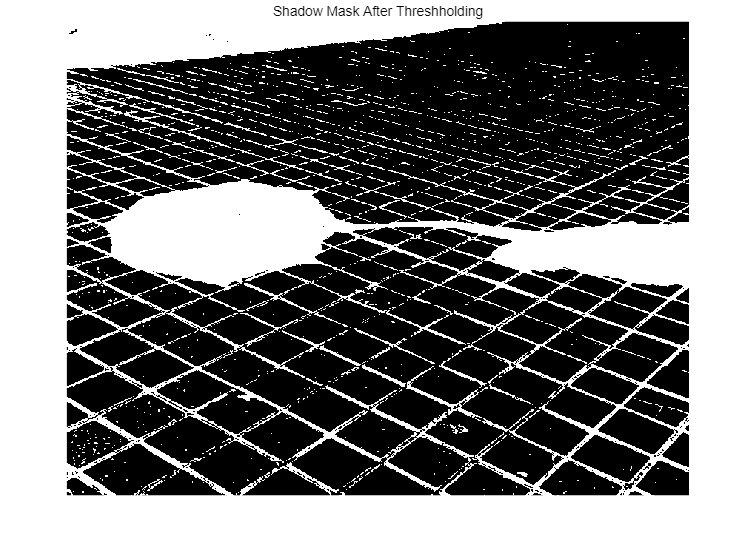

clear; clc;
% ---- 阴影检测 ----
% 读取原始图像和生成初始掩码
ratio = 3; % 阈值检测的参数，可正可负
radius = 3; % 做开运算去除噪声的半径
radius_erode = 6;  % 用于提取边界做腐蚀的半径
sigma = 2; % 生成高斯核
radius_dilate = 1; % 用于区域增长的半径（一般不改）
or_img = imread('../resources/_MG_5844.jpg');
y_cb_cr_img = rgb2ycbcr(or_img);
y_channel = y_cb_cr_img(:, :, 1); 
y_mean = mean(y_channel(:));
y_std = std(double(y_channel(:)));
threshold = y_mean - (y_std / ratio);
shadow_mask = y_channel < threshold;
% 显示初始mask
figure;
imshow(shadow_mask, []);
title("Shadow Mask After Threshholding");

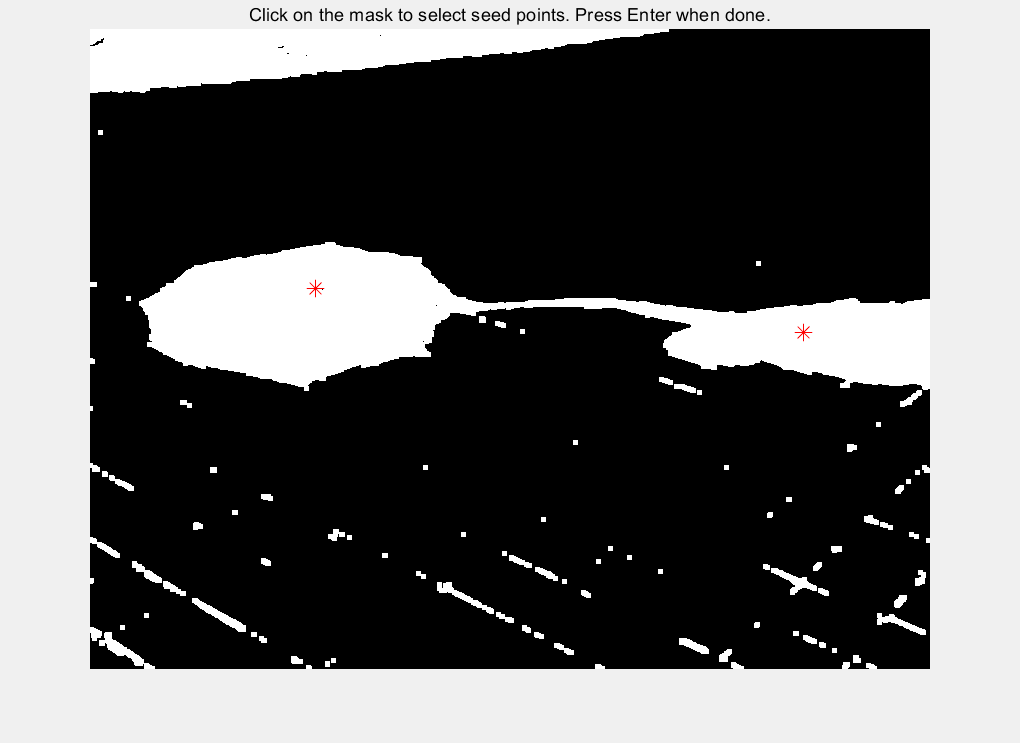


% 对初始mask做开运算
se1 = strel('disk', radius); 
open_mask = imopen(shadow_mask, se1); 

% 显示初始掩码并提示用户选择点
figure;
imshow(open_mask, []);
title('Click on the mask to select seed points. Press Enter when done.');
hold on;

% 交互式获取用户点击的基础点
[x, y] = ginput(); 
x = round(x);      
y = round(y);

% 验证用户选择的点是否在图像范围内
[h, w] = size(open_mask);
valid_points = (x > 0 & x <= w) & (y > 0 & y <= h);
x = x(valid_points);
y = y(valid_points);

% 在图像上标记用户选择的基础点
plot(x, y, 'r*', 'MarkerSize', 10);

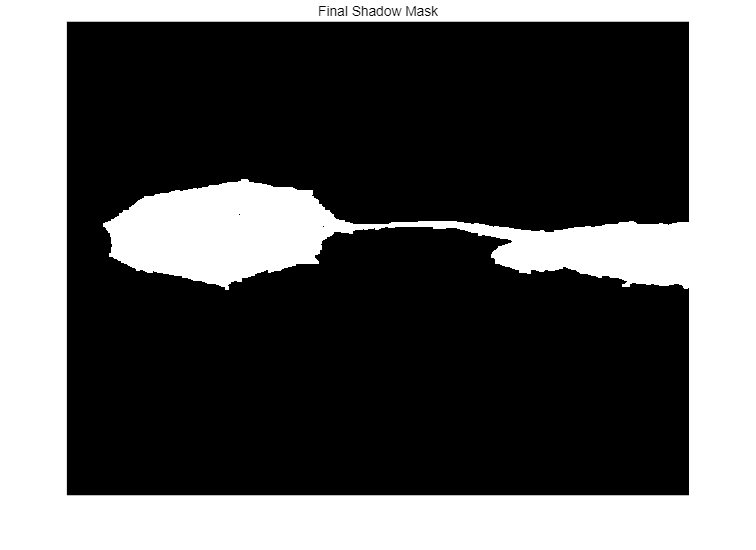

final_mask = false(size(open_mask));

% 区域增长
se = strel('disk', radius_dilate);
for i = 1:length(x)
    seed = false(size(open_mask)); 
    seed(y(i), x(i)) = true;          % 设置基础点为种子
    region = seed;
    % 扩张，直到区域稳定
    while true
        dilated = imdilate(region, se);    
        new_region = dilated & open_mask; 
        if isequal(new_region, region)     % 如果区域没有变化，则退出
            break;
        end
        region = new_region;               % 更新区域
    end
    final_mask = final_mask | region;
end
figure;
imshow(final_mask, []);
title('Final Shadow Mask');

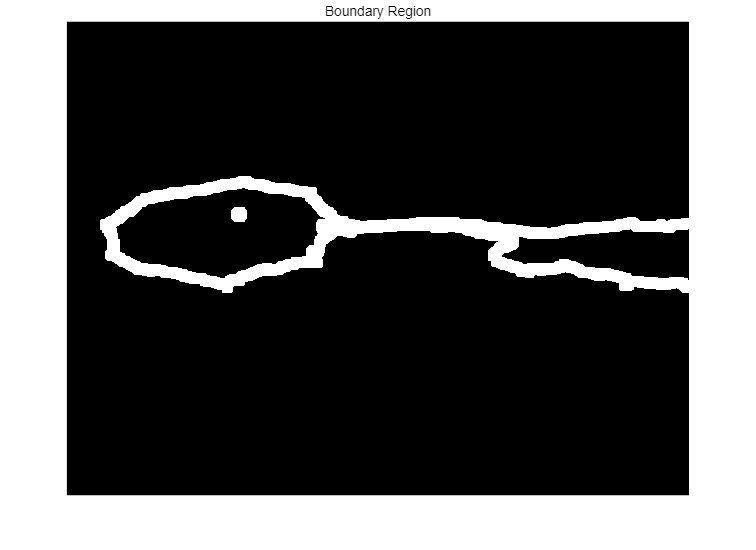

% ---- 阴影去除 ----
% 提取亮区和阴影区
shadow_region = final_mask;  % 阴影区
lit_region = ~final_mask;    % 非阴影区

% 进行掩膜腐蚀操作以提取边界
se_erode = strel('disk', radius_erode);
eroded_mask = imerode(final_mask, se_erode); % 腐蚀操作
boundary_region = final_mask & ~eroded_mask;    % 获取阴影边界
smooth_region = imdilate(boundary_region,se_erode);

figure;
imshow(smooth_region,[]);
title("Boundary Region");

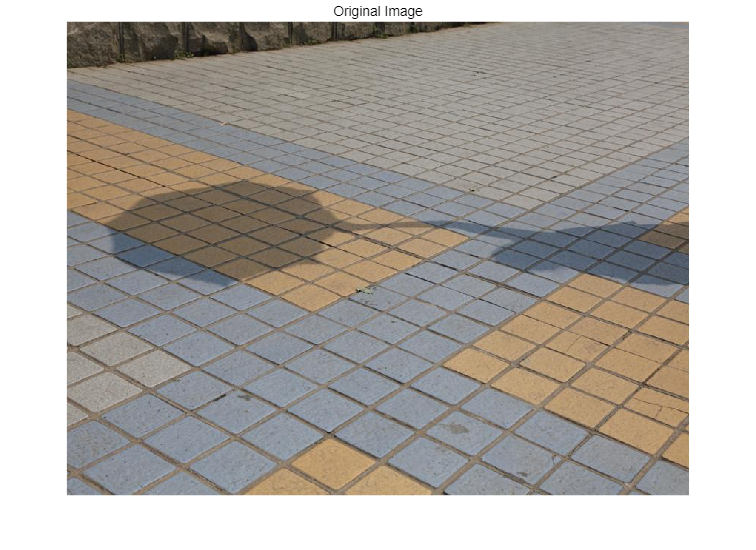

% 初始化去阴影图像（复制原始图像用于修改阴影区域）
corrected_img = double(or_img);

% 对 R, G, B 三个通道分别处理
for k = 1:3
    % 当前通道的阴影和亮区像素
    shadow_pixels = double(or_img(:, :, k)) .* shadow_region;
    lit_pixels = double(or_img(:, :, k)) .* lit_region;
    boundary_pixels = double(or_img(:, :, k)) .* boundary_region;

    % 计算阴影区域和亮区的均值
    shadow_mean = mean(shadow_pixels(shadow_pixels > 0));
    lit_mean = mean(lit_pixels(lit_pixels > 0));
    boundary_mean = mean(boundary_pixels(boundary_pixels > 0));

    % 计算阴影区域和亮区的标准差
    shadow_std = std(shadow_pixels(shadow_pixels > 0));
    lit_std = std(lit_pixels(lit_pixels > 0));
    boundary_std = std(boundary_pixels(boundary_pixels > 0));

    % 计算通道的 alpha_k 和 gamma_k
    gamma_k = lit_std / shadow_std;
    alpha_k = lit_mean - gamma_k * shadow_mean;

    gamma1_k = lit_std / boundary_std;
    alpha1_k = lit_mean - gamma1_k * boundary_mean;
    
    %阴影区域
    shadow_indices = find(shadow_region - boundary_region);
    corrected_channel = corrected_img(:, :, k); 
    corrected_channel(shadow_indices) = alpha_k + gamma_k * corrected_channel(shadow_indices);

    % 对边界区域
    boundary_indices = find(boundary_region);
    corrected_channel(boundary_indices) = alpha1_k + gamma1_k * corrected_channel(boundary_indices);

    % 对 smooth_region 应用高斯模糊

    h = fspecial('gaussian', 4 * sigma - 1, sigma);
    smoooth_indice = find(smooth_region);
    
    % 对于 smooth_region 区域应用高斯模糊
    blurred_area = imfilter(corrected_channel, h, 'replicate');
    
    % 将模糊区域更新到 corrected_channel
    corrected_channel(smoooth_indice) = blurred_area(smoooth_indice);
    
    corrected_img(:, :, k) = corrected_channel;
end

% 限制像素值范围 [0, 255]
corrected_img = uint8(min(max(corrected_img, 0), 255));

% 显示阴影去除结果
figure;
imshow(or_img);
title("Original Image");

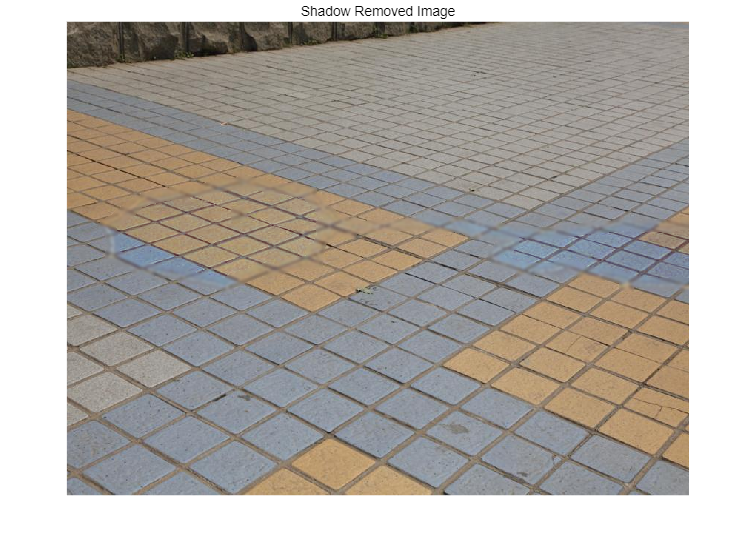

figure;
imshow(corrected_img);
title('Shadow Removed Image');